## Función con la dinámica del robot

function dxdt = RobotDynamics3dof(~, x, g, params, tau)

    m11 = cos(x(2))^2*params(1) + cos(x(2))*cos(x(2) + x(3))*params(2) + sin(x(2) + x(3))*params(3);
    m22 = params(1) + 2*cos(x(3))*params(2) + params(3);
    m23 = cos(x(3)) * params(2) + params(3);
    m32 = cos(x(3)) * params(2) + params(3);
    m33 = params(3);

    M = [m11 0   0;
        0   m22 m23;
        0   m32 m33];

    c11 = -cos(x(2))*sin(x(2))*x(5)*params(1) - 1/2*(cos(x(2))*sin(x(2) + x(3))*(x(5) + x(6)) + sin(x(2))*cos(x(2) + x(3))*x(5))*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*(x(5) + x(6))*params(3);
    c12 = -cos(x(2))*sin(x(2))*x(4)*params(1) - 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) + sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c13 = -1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c21 = cos(x(2))*sin(x(2))*x(4)*params(1) + 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) - sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c22 = -sin(x(3))*x(6)*params(2);
    c23 = -sin(x(3))*(x(5) + x(6))*params(2);
    c31 = 1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) - cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c32 = sin(x(5))*params(2);
    c33 = 0;

    C = [c11 c12 c13;
         c21 c22 c23;
         c31 c32 c33];

    d1=params(4)*x(4);
    d2=params(5)*x(5);
    d3=params(6)*x(6);

    D=[d1; d2; d3];

    g2 = g*(cos(x(2))*params(7) + cos(x(2) + x(3))*params(8));
    g3 = g*cos(x(2) + x(3))*params(8);

    g = [0;
        g2;
        g3];
    
    q_dot = [x(4); x(5); x(6)];

    q_ddot = M \ (tau - C * q_dot - D - g);

    dxdt = [q_dot;
        q_ddot];
end

## Solución de la ecuación diferencial

format long

params = [  0.00349359
            0.00246677
            0.00333632
            0.00076823
            0.03526735
            0.00744473
            0.00449158
            0.01701218
          ];

x0 = [pi/4; 0; 0; 0; 0; 0];
tspan = 0:0.01:5;
tau = 0;
g = 9.81;

[t, x] = ode45(@(t,x) RobotDynamics3dof(t, x, g, params, tau), tspan, x0);

## Gráficas de articulaciones

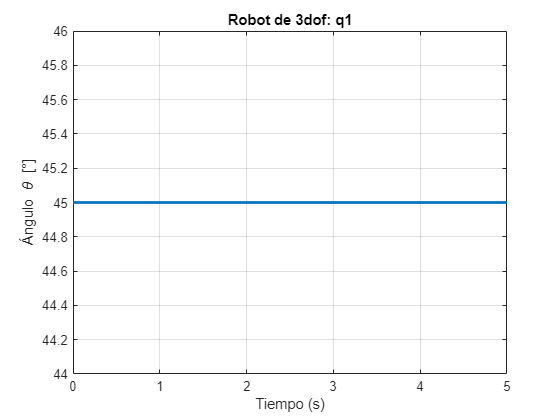

figure;
plot(t, x(:,1)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q1');
grid on;

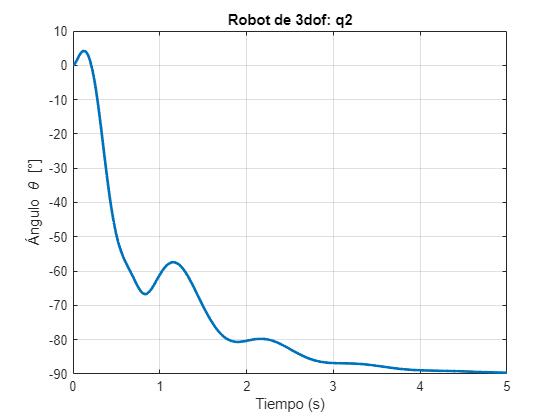


figure;
plot(t, x(:,2)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q2');
grid on;

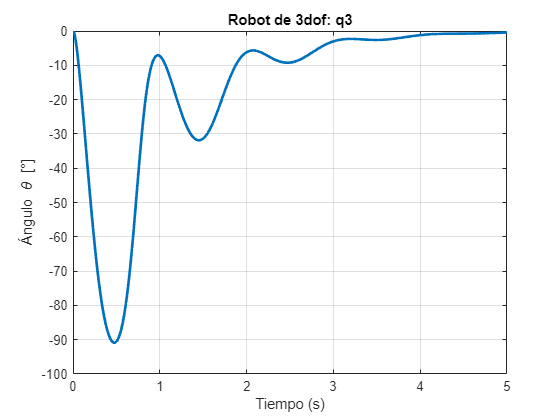


figure;
plot(t, x(:,3)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q3');
grid on;

## Animación

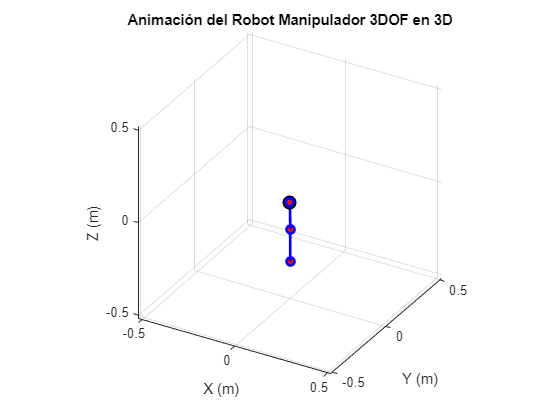

dh = ["q1", 0, 0,      pi/2; 
      "q2", 0, 0.145,  0   ; 
      "q3", 0, 0.1738, 0   ];

geomagic = Robot3dof(3, dh);

animarRobot3DOF3D(t, x, geomagic);